# Commande de vol latéral

alazard@isae.fr

BERGE Florent

GROUSSEAU Léa

KHERFOUCHE--BERNAUDAT Gaël

Description du modèle d'état:

- 
$$x=[\beta ; p; r; \phi ]$$


- 
$$u=[dp; dr]$$


- 
$$y = [n_y; p; r; \phi ]$$


a=[ -0.1400    0.0530   -0.9990    0.0470;
   -2.4610   -0.9920    0.2620         0;
    1.5950   -0.0410   -0.2670         0;
         0    1.0000    0.0530         0];
b=[0 0.03;0.404   0.26;0.00  -0.68;0 0];
c=[   -0.0003    0.0016   0.0016    0;...
         0       1.0000      0      0;...
         0         0      1.0000    0 ;...
         0         0         0    1.0000];
d=[0.0001   -0.0075;0 0;0 0;0 0];
plant=ss(a,b,c,d);
plant.u = {'dp','dr'};
plant.StateName = {'beta', 'p', 'r', 'phi'};

## Analyse en boucle ouverte

Analyse de la dynamique:

damp(plant)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.84e-03                 1.00e+00       3.84e-03         2.60e+02    
 -1.03e+00                 1.00e+00       1.03e+00         9.75e-01    
 -1.85e-01 + 1.33e+00i     1.38e-01       1.34e+00         5.41e+00    
 -1.85e-01 - 1.33e+00i     1.38e-01       1.34e+00         5.41e+00    


figure
pzmap(plant)

- En [0;-1]: mode de roulis pur

- En [0;0]: mode spirale

- Les deux pôles complexes conjugués: mode de roulis hollandais (mal amorti)

On observe que tous les poles sont à partie réelle négative donc le système est stable en BO mais le faible amortissement du roulis hollandais et la lenteur du mode spirale sont problématique pour le pilotage 

Réponse du système à une condition initiale sur $\beta$:

x0 = [1;0;0;0];
figure
initial(plant, x0)

On observe que les oscillations sont longues ( roulis holandais) couplé à une dérive lente sur $\phi$.

Réponse de $\beta$ et $\phi$ à des conditions initiales sur $\beta$ et $\phi$ sur un horizon de $10~s$:

figure
initial(ss(plant.a, plant.b, [1 0 0 0; 0 0 0 1],0), [1;0;0;0], 10) % C0 sur beta

On observe que la condition initiale sur $\beta$ entraine des oscillations sur $\beta$ ET $\phi$. Les deux états sont donc couplés.

figure
initial(ss(plant.a, plant.b, [1 0 0 0; 0 0 0 1],0), [0;0;0;1], 10) % C0 sur phi

De même, on observe que la condition initiale sur $\phi$ entraine des oscillations sur $\beta$ ET $\phi$, et un très faible amortissement (on passe de 1 à 0.9 en $10~s$). Les deux états sont donc couplés.

L'utilisation de la fonction *initial* suppose que l'on connait l'état du système, ce qui peut être laborieux quand on va reboucler des filtres et des correcteurs dynamiques. On préfère utiliser un schéma simulink avec 2 entrées fictives dont les réponses impulsionnelles correspondent aux réponses à des conditions initiales sur $\beta$ et $\phi$.

D'où le schéma simulink:

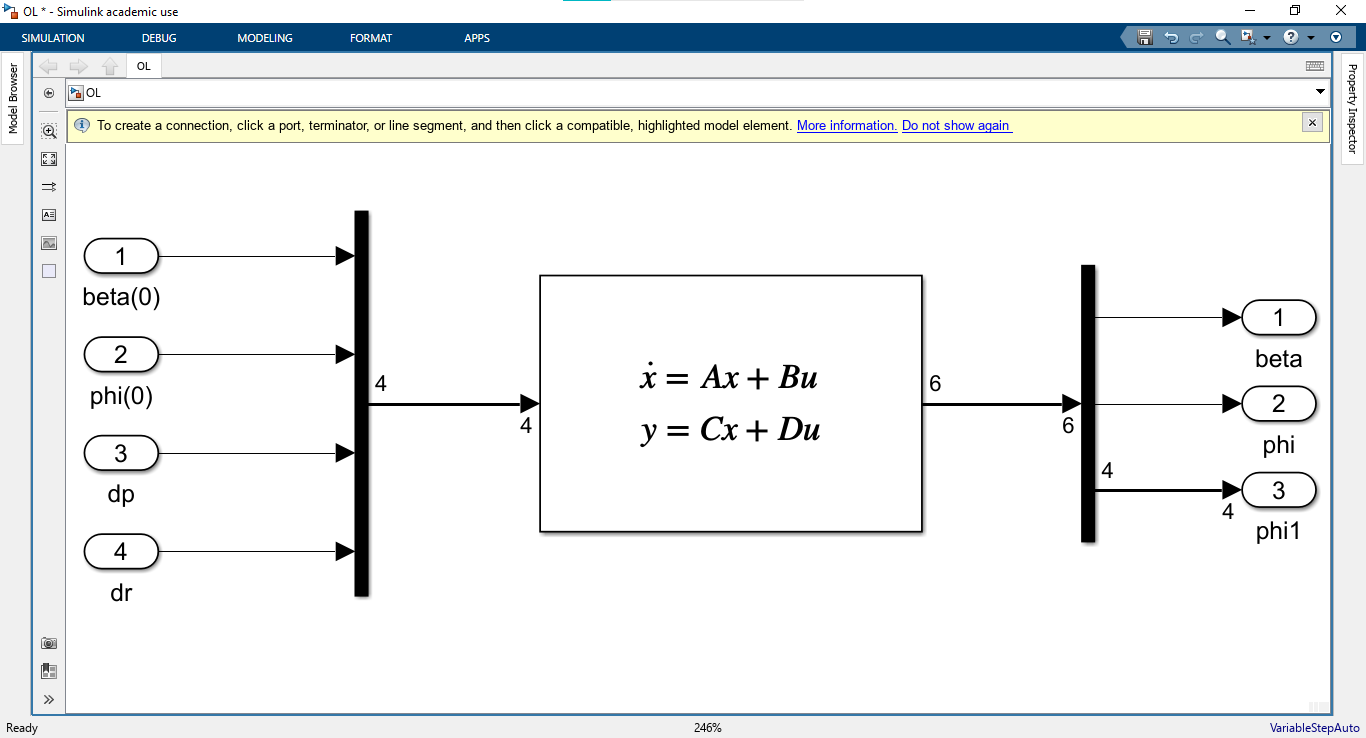

BO = linearize('OL');
figure

Réponse impulsionnelle:

impulse(BO(1:2,1:2),10) % on regarde les sorties 1 et 2 (beta, hi) pour une impulsion en entrée 1 et 2 (beta(0), phi(0))

## Commande modale (placement de pôles)

### Commande modale non découplante

lda = [-1.1; -1; -1+1.3i; -1-1.3i]; % Placement des pôles
Kx = place(plant.a,plant.b,lda);
K = Kx*inv(plant.c-plant.d*Kx) % u = K*y

Vérification:

damp(feedback(plant, K))

Marge de module:

figure
sigma(eye(2)+K*plant)
S=inv(eye(2)+K*plant);
r=1/norm(S,'inf')

La marge de module est très faible (<0.5), ce qui rend le système très sensible aux incertitudes de modélisation.

Comparaison boucle ouverte et boucle fermée

BF = lft(BO,-K);
figure
impulse(BO(1:2,1:2),BF,10)
legend("BO","BF")

La réponse à une impulsion $\phi$ en boucle fermée a une influence sur $\beta$. Les modes ne sont pas découplés. On observe cependant que le gain K obtenu stabilise bien le système.

Calcul de la précommande $H$à partir du système en boucle fermée pour avoir un gain statique unitaire.

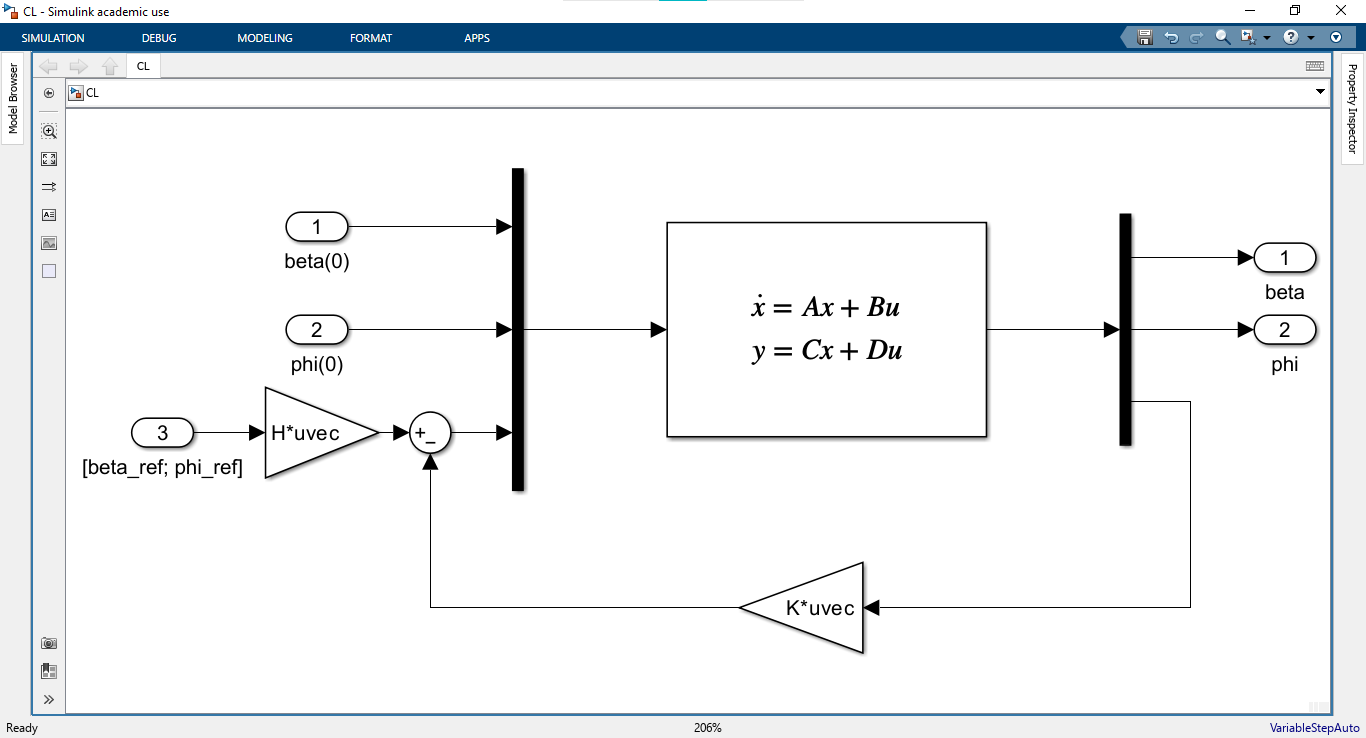

H = eye(2);
Gbf = linearize('CL1');
% figure
% step(Gbf(1:2,3:4))
H = inv(dcgain(Gbf(1:2,3:4)));
Gbf = linearize('CL1');
figure
step(Gbf(1:2,3:4))

La précommande H assure le gain statique unitaire du système, $\beta$ et $\phi$ tendent vers leurs valeurs de référence en régime permanent après une impulsion. 

Un couplage transitoire est cependant toujours présent. 

### Commande modale découplante

On impose ici les vecteurs propres associés aux valeurs propres précédentes, les modes réelles sont découplés de $\beta$ et les modes complexes de $\phi$.

v1w1 = null([plant.a-lda(1)*eye(4) plant.b; 1 0 0 0 0 0]);
v2w2 = null([plant.a-lda(2)*eye(4) plant.b; 1 0 0 0 0 0]);
v3w3 = null([plant.a-lda(3)*eye(4) plant.b; 0 0 0 1 0 0]);
v4w4 = null([plant.a-lda(4)*eye(4) plant.b; 0 0 0 1 0 0]);
V = [v1w1(1:4) v2w2(1:4) v3w3(1:4) v4w4(1:4)];
W = [v1w1(5:6) v2w2(5:6) v3w3(5:6) v4w4(5:6)];
Kx = -W*inv(V);
Kx = real(Kx);
K = Kx*inv(plant.c-plant.d*Kx);

Vérification

damp(feedback(plant, K))

Marge de module

figure
sigma(eye(2)+K*plant)
S=inv(eye(2)+K*plant);
r=1/norm(S,'inf')

Comparaison boucle ouverte et boucle fermée

BF = lft(BO,-K)
figure
impulse(BO(1:2,1:2),BF,10)
legend("BO","BF")
H = eye(2);
Gbf = linearize('CL1');
% figure
% step(Gbf(1:2,3:4))
H = inv(dcgain(Gbf(1:2,3:4)));
Gbf = linearize('CL1');
figure
step(Gbf(1:2,3:4))

On observe que les réponses indicielles et impulsionnelles sont désormais découplées, les deux valeurs tendent respectivement vers leur valeur de référence mais avec un léger dépassement pour $\beta$. L'amortissement $\xi$ est donc inférieur à 1.

## Commande LQ

On cherche à minimiser $J= \int_0^\infty x^TQ_xx+u^TRu~dt$

On ne va pondérer que $r$ et 

qr=7;qphi=2;
Qx = diag([0 0 qr qphi]);
R = eye(2);
[Kx,Px,dyn] = lqr(plant.a,plant.b,Qx,R);
Kx
damp(dyn)

Pourquoi choisit-on de ne pondérer que $r$ et $\phi$?

Observons l'évolution de la dynamique en boucle fermée en fonction de $\rho$ lorsque l'on pondère $\beta$ seul:


$$J= \int_0^\infty \beta^2+\rho(dp^2+dr^2)dt$$


addpath("bib1\")
figure
rsqlocus(plant.a,plant.b,diag([1 0 0 0]), eye(2)); % ponderer beta seul

Quelque soit le réglage de $\rho$, il n'est pas possible de modifier les modes spirale et roulis pur.

Lorsque l'on pondère $p$ seul:


$$J= \int_0^\infty p^2+\rho(dp^2+dr^2)dt$$


figure
rsqlocus(plant.a,plant.b,diag([0 1 0 0]), eye(2));

De même il n'est pas possible d'accélérer le mode spirale.

Lorsque l'on pondère $r$ seul:


$$J= \int_0^\infty r^2+\rho(dp^2+dr^2)dt$$


figure
rsqlocus(plant.a,plant.b,diag([0 0 1 0]), eye(2));

Le réglage de $\rho$ permet d'amortir le roulis hollandais.

Lorsque l'on pondère $\phi$ seul:


$$J= \int_0^\infty \phi^2+\rho(dp^2+dr^2)dt$$


figure
rsqlocus(plant.a,plant.b,diag([0 0 0 1]), eye(2));

Ce réglage permet d'accélérer le mode spirale.

K = Kx*inv(plant.c-plant.d*Kx);

Marge de module

figure
sigma(eye(2)+K*plant)
S=inv(eye(2)+K*plant);
r=1/norm(S,'inf') % 0.8, pas égale à 1 car retour de sortie; Si retour d'état r>=1;
BF = lft(BO,-K);
figure
impulse(BO(1:2,1:2),BF,10)
legend("BO","BF")

Gain statique

H = eye(2);
Gbf = linearize('CL1');
% figure
% step(Gbf(1:2,3:4))
H = inv(dcgain(Gbf(1:2,3:4)));
Gbf = linearize('CL1');
figure
step(Gbf(1:2,3:4))

Cependant, cette méthode ne permet pas de découpler les modes comme le montre ces réponses indicielles.

## Commande LQ avec modèle de référence implicite

On souhaite un découplage parfait, soit:

- Dynamique de lacet: $\ddot{\beta}+2\xi_l\omega_l\dot{\beta}+\omega_l^2\beta$

- Dynamique de roulis: $\ddot{\phi}+2\xi_r\omega_r\dot{\phi}+\omega_r^2\phi$

On rappel $\dot{\beta}=-r$ et $\dot{\phi}=p$.

Il suit:


$$\dot{x}=A_dx$$
 

wr  = 1.049;
wl  = 1.64;
xir = 1.001;
xil = 0.61;
Ad  = [0 0 -1 0; 0 -2*xir*wr 0 -wr^2; wl^2 0 -2*xil*wl 0; 0 1 0 0];
damp(Ad)
Qx=(plant.a-Ad)'*(plant.a-Ad);
R=(plant.b'*plant.b);
S=(plant.a-Ad)'*plant.b;
[Kx,Px,dyn] = lqr(plant.a, plant.b, Qx, R, S);
damp(dyn)
K = Kx*inv(plant.c-plant.d*Kx);

Marge de module

figure
sigma(eye(2)+K*plant)
S=inv(eye(2)+K*plant);
r=1/norm(S,'inf')
BF = lft(BO,-K);
figure
impulse(BO(1:2,1:2),BF,10)
legend("BO","BF")

Gain statique

H = eye(2);
Gbf = linearize('CL1');
% figure
% step(Gbf(1:2,3:4))
H = inv(dcgain(Gbf(1:2,3:4)));
Gbf = linearize('CL1');
figure
step(Gbf(1:2,3:4))

On observe des performances similaires à celles obtenues par la méthode de placement de vecteurs propres. Le découplage est correct, on observe une légère oscillation de $\phi$ pour un échelon de $\beta$.

## Controleur $H_\infty$ à 2 degrés de liberté

On utilise le schéma simulink suivant:

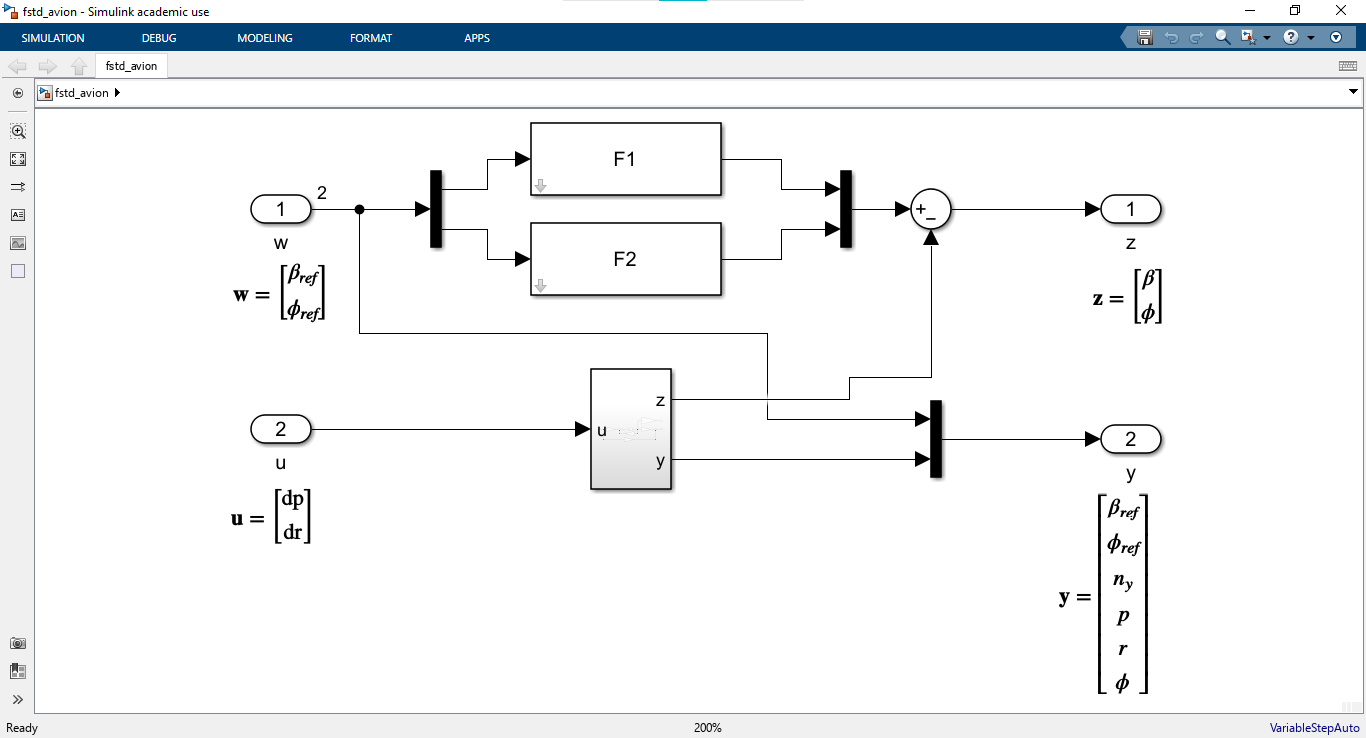

Les filtres $F1$ et $F2$ sont choisis à partir des équations de découplage:

F1=tf(wl^2, [1 2*xil*wl wl^2]);
F2=tf(wr^2, [1 2*xir*wr wr^2]);

P= linearize('fstd_avion');
damp(P);

Synthèse $H_\infty$ "full order":

[Kinf, CL, gamma]=hinfsyn(P,6,2);
gamma

En régime permanent, l'erreur est inférieure ou égale à gamma. La sortie suit donc quasi parfaitement le modèle de référence.

Analyse du controleur:

BF2=linearize('CL2');

Réponse à des échelons $\beta_{ref}$ et $\phi_{ref}$:

figure
step(BF2(1:2,3:4),10)
figure
impulse(BO(1:2,1:2),BF2(1:2,1:2),10); legend("BO", "BF2");

Le suivi de consigne est très bon, cependant le controleur ne rejette pas du tout les perturbations (conditions initiales sur $\beta$ et $\phi$) (comportement similaire à la boucle ouverte).

damp(Kinf)

Il y a dans le correcteur des modes très rapides qui poseraient problème lors de l'implémentation dans le calculateur de bord.

## Synthèse $H_\infty$ d'un contrôleur statique (systune)

Définition des paramètres à tuner:

Kinf = tunableGain("K2ddl",2,6); % Gain
CL0 = lft(P, Kinf);
CL0.u={'beta_ref','phi_ref'};
CL0.y={'d_beta','d_phi'};

Critère:

Req = TuningGoal.Gain({'beta_ref','phi_ref'},{'d_beta','d_phi'},1); % On minimise l'erreur statique

Lancement

options = systuneOptions('MaxIter', 120000,'Display','sub','RandomStart',5);
[CLopt,fSoft,~,info] = systune(CL0,Req,[],options);
figure
viewGoal(Req,CLopt)

Le critière fsoft est bien inférieur à 1. Le cahier des charges est bien respecté.

Kinf =  getValue(Kinf,CLopt)

Analyse du contrôleur:

BF2=linearize('CL2');
figure
step(BF2(1:2,3:4),10)

Le suivi de consigne est bon, les états sont bien découplés.

figure
impulse(BO(1:2,1:2),BF2(1:2,1:2),10); legend("BO","BF2")

Les perturbations sont bien rejetées, contrairement au full-order.

Réponse indicielle sur les braquages des gouvernes:

BF3 = linearize('CL3');
figure
step(BF3(:,3:4),10)

On observe que les deux gouvernes interviennent dans la correction des angles $\beta$ et $\phi$.

## Synthèse $H_2$ d'un contrôleur statique

Dans ce cas, on fixe l'erreur à $0.05$ (nous avions trouvé une solution de $0.028$ à la partie précédente). On cherche alors un correcteur qui minimise l'énergie de commande (norme $H_2$).

Le nouveau problème standard de commande:

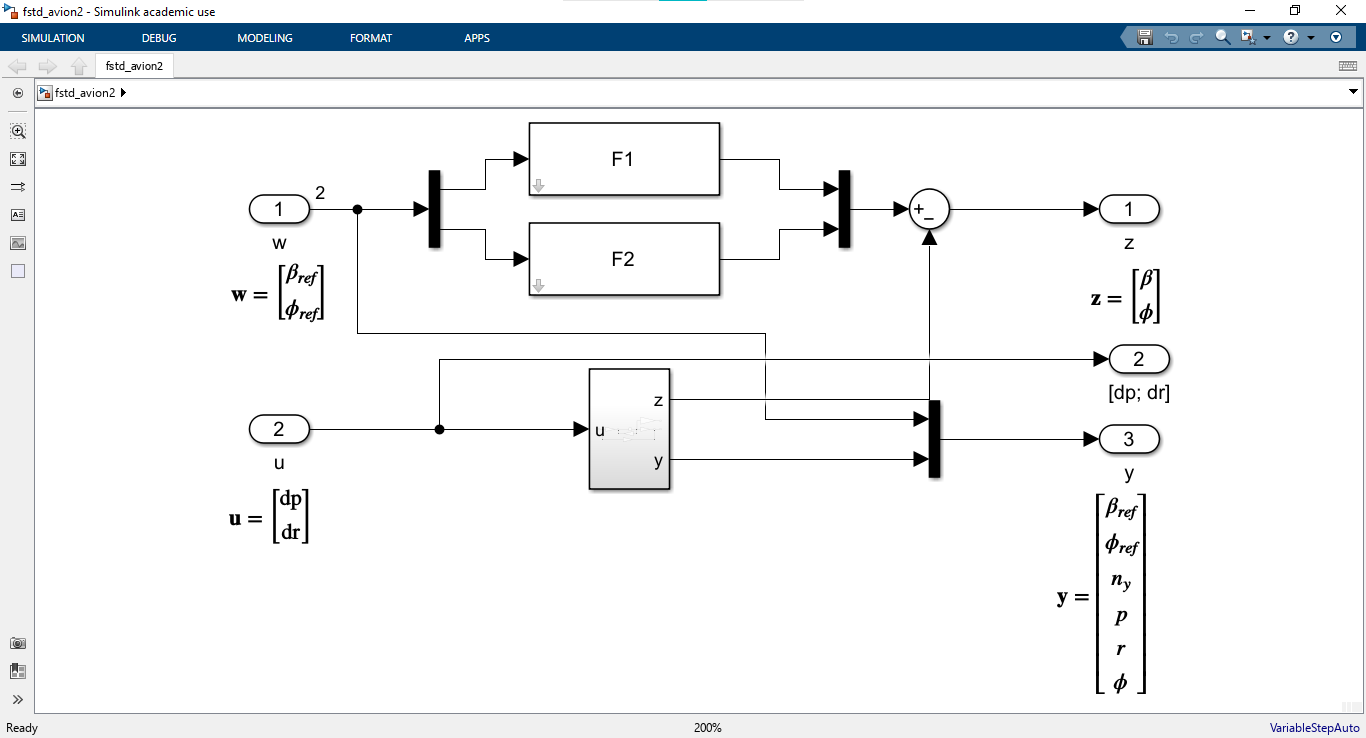

P= linearize('fstd_avion2')
Ksec = tunableSS("Ksec",2,2,6); % Gain
CL0  = lft(P, Ksec);
% CL0.u
% CL0.y

Critères:

Reqsoft = TuningGoal.Variance('w','[dp; dr]',100);
Reqhard = TuningGoal.Gain('w','fstd_avion2/z',0.05); % Contrainte H_inf sur l'erreur statique

Lancement

options = systuneOptions('MaxIter', 120000,'Display','sub','RandomStart',2);
[CLopt,fSoft,~,info] = systune(CL0,Reqsoft,Reqhard,options);
figure
% evalGoal(Reqsoft,CLopt)
viewGoal(Reqhard,CLopt)

Le systune avec contrôleur d'ordre 2 trouve Hard ≈ 1.0 (contrainte H∞ active, juste satisfaite) et Soft = 0.11.

Kinf = getValue(Ksec,CLopt);
BF3  = linearize('CL3');
figure
step(BF3(1:2,3:4),10)
impulse(BO(1:2,1:2),BF3(1:2,1:2),10); legend('BO','BF3');

La réponse indicielle et impulsionnelle montrent un bon compromis : le suivi est maintenu, le rejet de perturbation est amélioré par rapport à la BO, et l'énergie de commande est minimisée.